# Prac2

## Polynomial Regression

NOTE: You may have install Curve Fitting Toolbox from Apps => Get More Apps

Doing it without CFT:

## Q1

Create sin function.

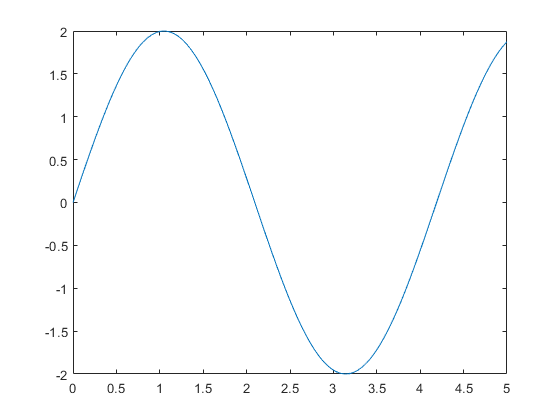

x = linspace(0,5,100);
y0 = 2*sin(1.5.*x);
figure;
plot(x,y0);

Randomly select points along X to create false data. Do so twice: once for training and once for validation.

xrand1 = 5.*rand(20,1);
%xrand1 = sort(xrand1);
xrand2 = 5.*rand(20,1);
%xrand2 = sort(xrand2);

Calculate sin value at random x points, add normally distributed noise. You can multiply element-wise by some standard deviation if you want a noisier distritbution.

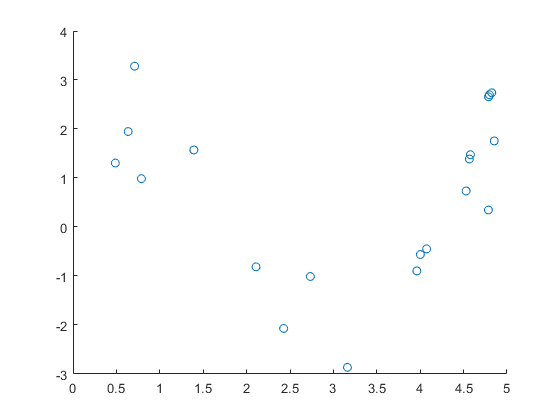

yrand1 = 2*sin(1.5.*xrand1) + randn(20,1); 
yrand2 = 2*sin(1.5.*xrand2) + randn(20,1);
scatter(xrand1,yrand1);

Create your figure. Break it into 9 subplots. For each subplot, plot your sign function, scatter your false data, then calculate and plot your line of best fit.

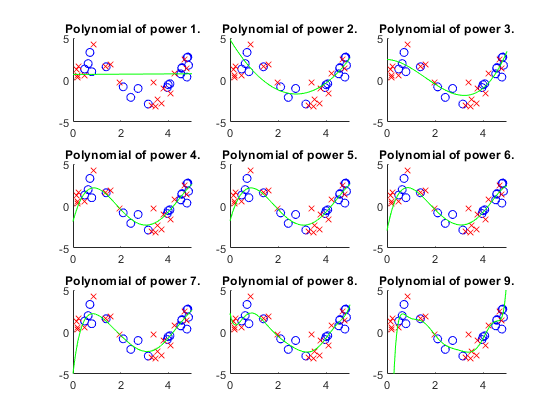

figure
trainError = zeros(9,20);
valError = zeros(9,20);
trainSSE = zeros(9,1);
valSSE = zeros(9,1);
valRMSE = zeros(9,1);

for R = 1:9
%Create new plot.
subplot(3,3,R);
hold on;

%Draw sin function, and false data.
%plot(x,y0, 'k');
scatter(xrand1,yrand1, 'ob');
scatter(xrand2,yrand2, 'xr');

%Create polynomial function that tries to fit false data.
poly = polyfit(xrand1,yrand1,R);

%Calculate y value at each x value, using polynomial function. Plot.
y = polyval(poly,x);
plot(x, y, 'g');

%Make plot look nice and prepare for new plot.
xlim([0,5]);
ylim([-5,5]);
title(sprintf('Polynomial of power %d.', R));
hold off;

trainError(R,:) = yrand1 - polyval(poly, xrand1);
valError(R,:) = yrand2 - polyval(poly,xrand2);
trainSSE(R) = sum(trainError(R,:).^2);
valSSE(R) = sum(valError(R,:).^2);
valRMSE(R) = std(valError(R,:));

end

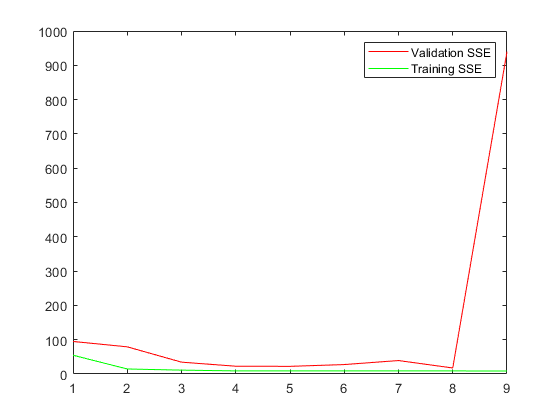

figure
plot(1:9,valSSE,'r',1:9,trainSSE,'g');
legend('Validation SSE','Training SSE')

## Parametric Probabilistic Classifier

Separate training input into data and classification.

Calculate training mean for each class.

mA = mean(data(classes));
mB = mean(data(~classes));

Calculate training variance for each class.

sd2A = var(data(classes));
sd2B = var(data(~classes));

Declare priors (proportion of each class in the dataset).

pA = 0.5;
pB = 0.5;

Generate domain for plots.

if mA + 2*sd2A > mB + 2*sd2B
    xmax = mA + 2*sd2A;
else
    xmax = mB + 2*sd2B;
end
if mA - 4*sd2A < mB - 4*sd2B
    xmin = mA - 4*sd2A;
else
    xmin = mB - 4*sd2B;
end
x = linspace(xmin,xmax,100);

Calculate the likelihood of each class over the domain of the data. Assume Gaussian (Normal) distribution.

lA = normpdf(x,mA,sqrt(sd2A));
lB = normpdf(x,mB,sqrt(sd2B));

if max(lA) > max(lB)
    lmax = max(lA);
else
    lmax = max(lB);
end

Calculate the posterior over the domain of the data.

postA = lA.*pA./(lA.*pA+lB.*pB);
postB = lB.*pB./(lA.*pA+lB.*pB);

if max(postA) > max(postB)
    postMax = max(postA);
else
    postMax = max(postB);
end

Plot.

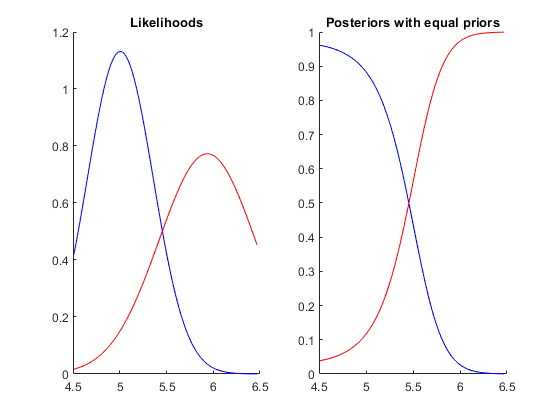

figure;
subplot(1,2,1);
hold on;
plot(x,lA,'b',x,lB,'r');
%xlim([xmin,xmax]);
%ylim([0,lmax]);
title('Likelihoods');
hold off;
subplot(1,2,2);
hold on;
plot(x,postA,'b',x,postB,'r');
%xlim([xmin,xmax]);
%ylim([0,postMax]);
title('Posteriors with equal priors');
hold off;